clearvars

## Learn++.NSE testing on Nonstationary datasets used in COMPOSE and FAST COMPOSE

### 1 Class Diagonal Translation

Average Error = 0.4375


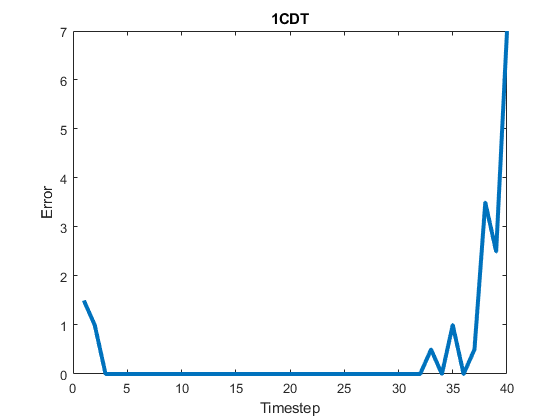

dataset = "X1CDT";
model.type = 'SVM';          % base classifier
model.kernel = 'Linear';
net.a = .5;                   % slope parameter to a sigmoid
net.b = 10;                   % cutoff parameter to a sigmoid
net.threshold = 0.01;         % how small is too small for error
net.mclass = 2;               % number of classes in the prediciton problem
net.base_classifier = model;  % set the base classifier in the net struct
net.initialized = true;
net.classifiers = {};   % classifiers
net.w = [];             % weights 
net.initialized = false;% set to false
net.t = 1;              % track the time of learning
net.classifierweigths = {};               % array of classifier weights
net.type = 'learn++.nse';
runLearnPlusPlusDotNse(dataset,net);

### 1 Class Horizontal Translation

Average Error = 1.1375


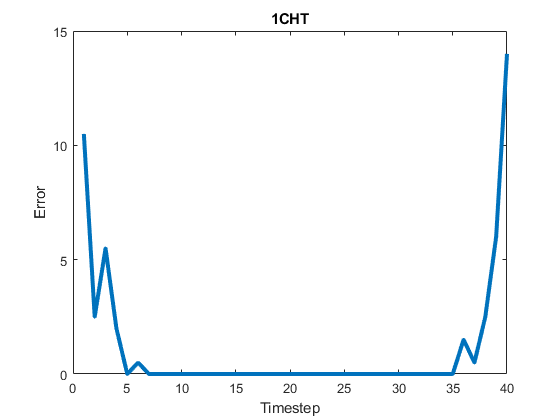

dataset = "X1CHT";
runLearnPlusPlusDotNse(dataset,net);

### 2 Class Diagonal Translation

Average Error = 6.125


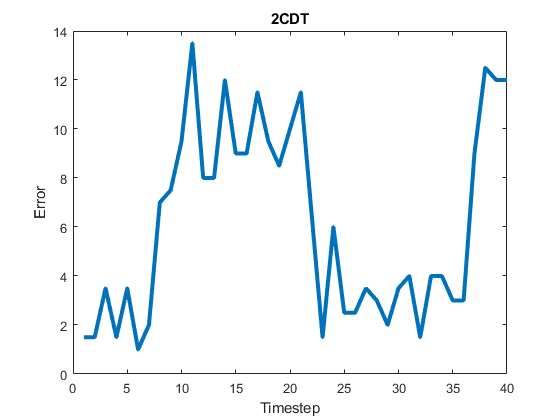

dataset = "X2CDT";
[nseResults2,nseData] = runLearnPlusPlusDotNse(dataset,net);

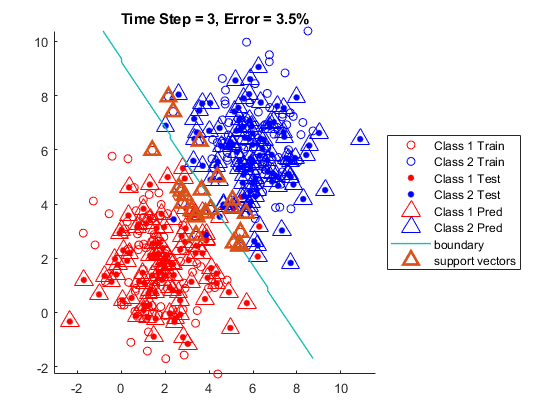

timeStep = 3;
plotResults(nseResults,nseData,timeStep)

### 2 Class Horizontal Translation

Average Error = 12.65


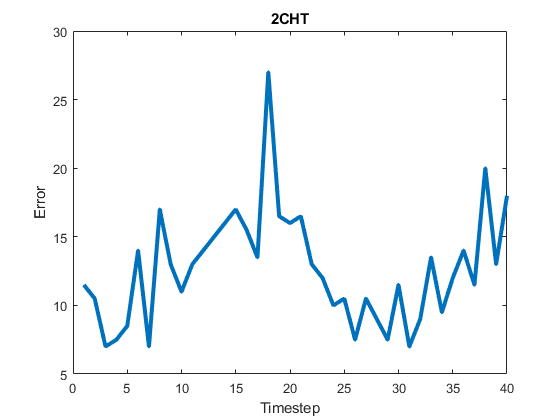

dataset = "X2CHT";
runLearnPlusPlusDotNse(dataset,net);

### 5 Class Vertical Translation (More than two classes ignoring for now)

% dataset = "X5CVT";
% model.type = 'SVM';          % base classifier
% net.a = .5;                   % slope parameter to a sigmoid
% net.b = 10;                   % cutoff parameter to a sigmoid
% net.threshold = 0.01;         % how small is too small for error
% net.mclass = 5;               % number of classes in the prediciton problem
% net.base_classifier = model;  % set the base classifier in the net struct
% runLearnPlusPlusDotNse(dataset,net)

### 1 Class Surrounding another Class (throws error in learn_nse_for_attacking.m, check preprocessing)

% dataset = "X1CSurr";
% model.type = 'SVM';          % base classifier
% net.a = .5;                   % slope parameter to a sigmoid
% net.b = 10;                   % cutoff parameter to a sigmoid
% net.threshold = 0.01;         % how small is too small for error
% net.mclass = 2;               % number of classes in the prediciton problem
% net.base_classifier = model;  % set the base classifier in the net struct
% runLearnPlusPlusDotNse(dataset,net)

### 4 Class Expanding 1 Class Fixed (More than two classes ignoring for now)

% dataset = "X4CE1CF";
% model.type = 'SVM';          % base classifier
% net.a = .5;                   % slope parameter to a sigmoid
% net.b = 10;                   % cutoff parameter to a sigmoid
% net.threshold = 0.01;         % how small is too small for error
% net.mclass = 4;               % number of classes in the prediciton problem
% net.base_classifier = model;  % set the base classifier in the net struct
% runLearnPlusPlusDotNse(dataset,net)

### 4 Class Rotating Separated (More than two classes ignoring for now)

% dataset = "X4CR";
% model.type = 'SVM';          % base classifier
% net.a = .5;                   % slope parameter to a sigmoid
% net.b = 10;                   % cutoff parameter to a sigmoid
% net.threshold = 0.01;         % how small is too small for error
% net.mclass = 4;               % number of classes in the prediciton problem
% net.base_classifier = model;  % set the base classifier in the net struct
% runLearnPlusPlusDotNse(dataset,net)

### 4 Class Rotating With Expansion Version 1(More than two classes ignoring for now)

% dataset = "X4CRE_V1";
% model.type = 'SVM';          % base classifier
% net.a = .5;                   % slope parameter to a sigmoid
% net.b = 10;                   % cutoff parameter to a sigmoid
% net.threshold = 0.01;         % how small is too small for error
% net.mclass = 4;               % number of classes in the prediciton problem
% net.base_classifier = model;  % set the base classifier in the net struct
% runLearnPlusPlusDotNse(dataset,net)

### 4 Class Rotating With Expansion Version 2 (More than two classes ignoring for now)

% dataset = "X4CRE_V2";
% model.type = 'SVM';          % base classifier
% net.a = .5;                   % slope parameter to a sigmoid
% net.b = 10;                   % cutoff parameter to a sigmoid
% net.threshold = 0.01;         % how small is too small for error
% net.mclass = 4;               % number of classes in the prediciton problem
% net.base_classifier = model;  % set the base classifier in the net struct
% runLearnPlusPlusDotNse(dataset,net)

### 2 Bidimensional Classes As Four Gaussians

Average Error = 15.724


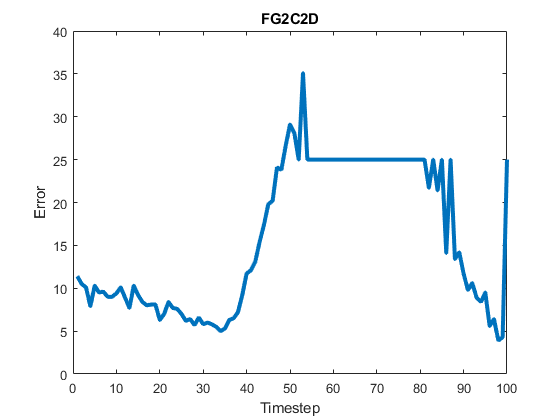

dataset = "FG_2C_2D";
runLearnPlusPlusDotNse(dataset,net);

### 2 Bidimensional Multimodal Gaussian Classes

Average Error = 12.939


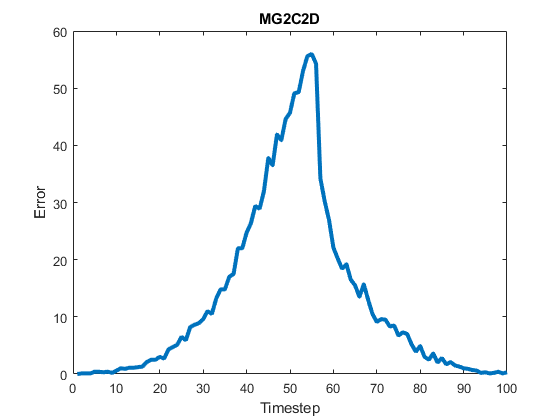

dataset = "MG_2C_2D";

runLearnPlusPlusDotNse(dataset,net);

### 2 Bidimensional Unimodal Gaussian Classes

Average Error = 4.678


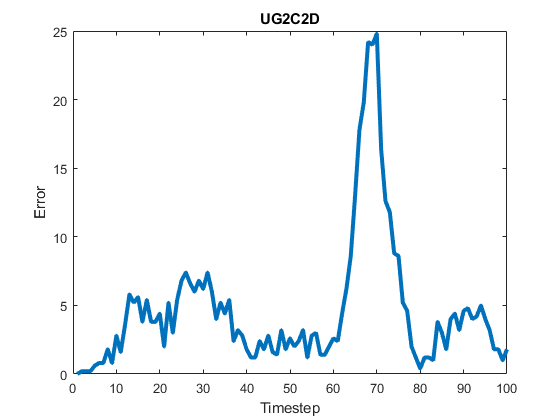

dataset = "UG_2C_2D";
runLearnPlusPlusDotNse(dataset,net);

### Two 3-dimensional Unimodal Gaussian Classes

Average Error = 5.847


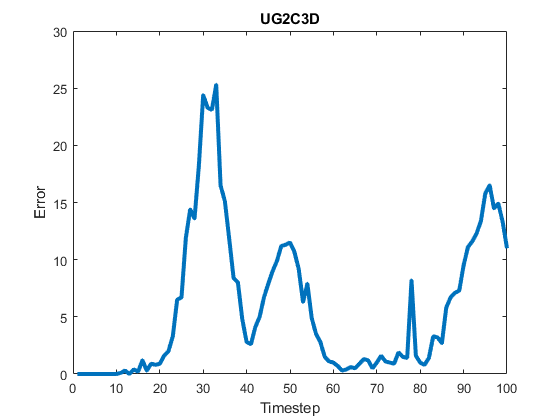

dataset = "UG_2C_3D";
runLearnPlusPlusDotNse(dataset,net);

### Two 5-dimensional Unimodal Gaussian Classes

Average Error = 8.047


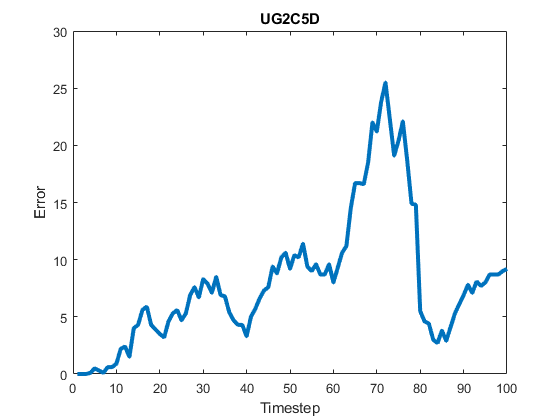

dataset = "UG_2C_5D";
runLearnPlusPlusDotNse(dataset,net);

### 2 Rotating Gears

Average Error = 4.145


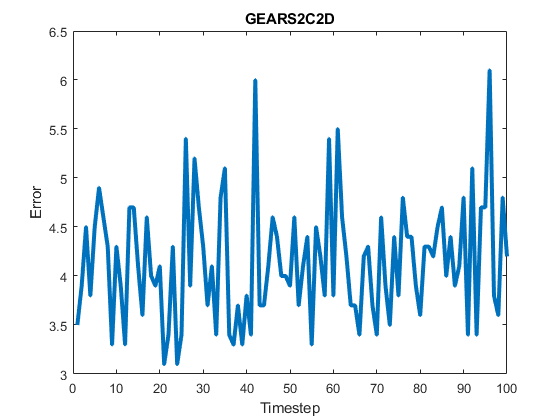

dataset = "GEARS_2C_2D";
runLearnPlusPlusDotNse(dataset,net);

### Keystroke dataset (More than two classes, ignoring for now)

% dataset = "Keystroke";
% model.type = 'SVM';          % base classifier
% net.a = .5;                   % slope parameter to a sigmoid
% net.b = 10;                   % cutoff parameter to a sigmoid
% net.threshold = 0.01;         % how small is too small for error
% net.mclass = 2;               % number of classes in the prediciton problem
% net.base_classifier = model;  % set the base classifier in the net struct
% runLearnPlusPlusDotNse(dataset,net)

## Helper Functions

### Function for running Learn++.NSE

function [nseResults,nseData] = runLearnPlusPlusDotNse(dataset,net)
    [nseResults,nseData,~,~,~,numTimeSteps] = loadNseDataset(dataset,net);
    for iTStep = 1:numTimeSteps
        if iTStep == 1
            [nseResults(iTStep).net,...
            nseResults(iTStep).f_measure,...
            nseResults(iTStep).g_mean,...
            nseResults(iTStep).precision,...
            nseResults(iTStep).recall,...
            nseResults(iTStep).errs_nse,...
            nseResults(iTStep).latestClassifier] = learn_nse_for_attacking(nseResults(iTStep).net,...
                                                nseData(iTStep).dataTrain,...
                                                nseData(iTStep).labelsTrain,...
                                                nseData(iTStep).dataTest,...
                                                nseData(iTStep).labelsTest);
        else
            [nseResults(iTStep).net,...
            nseResults(iTStep).f_measure,...
            nseResults(iTStep).g_mean,...
            nseResults(iTStep).precision,...
            nseResults(iTStep).recall,...
            nseResults(iTStep).errs_nse,...
            nseResults(iTStep).latestClassifier] = learn_nse_for_attacking(nseResults(iTStep-1).net,...
                                                nseData(iTStep).dataTrain,...
                                                nseData(iTStep).labelsTrain,...
                                                nseData(iTStep).dataTest,...
                                                nseData(iTStep).labelsTest);
        end
    end
    nseErrorPlot(dataset,nseResults,numTimeSteps);
end

### Dataset loading function

function [nseResults,nseData,numObs,numDims,numClasses,numTimeSteps] = loadNseDataset(dataset,net)
    x = load("Synthetic Datasets\" + dataset + ".mat");
    data_train = x.(dataset).dataTrain;
    data_test = x.(dataset).dataTest;
    labels_test = x.(dataset).labelsTest;
    labels_train = x.(dataset).labelsTrain;
    T = length(data_train);
    for t = 1:T
      data_train{t} = data_train{t};
      labels_train{t} = labels_train{t};
      data_test{t} = data_test{t};
      labels_test{t} = labels_test{t};
    end
    
    numTimeSteps = length(data_train);
    [numObs, numDims] = size(data_train{1});
    numClasses = numel(unique(labels_train{1}));
    
    nseData = repmat(struct("dataTrain",zeros(numObs,numDims),...
                        "dataTest",zeros(numObs,numDims),...
                        "labelsTrain",zeros(numObs,1),...
                        "labelsTest",zeros(numObs,1)),1,numTimeSteps);
    [nseData.dataTrain] = data_train{:};
    [nseData.dataTest] = data_test{:};
    [nseData.labelsTrain] = labels_train{:};
    [nseData.labelsTest] = labels_test{:};

nseResults = repmat(struct("net",net,...
                              "f_measure",zeros(1,net.mclass),...
                              "g_mean",0,...
                              "recall",zeros(1,net.mclass),...
                              "precision",zeros(1,net.mclass),...
                              "errs_nse",0,...
                              "latestClassifier",0),1,numTimeSteps);

end

### Plotting Functions

function [] = nseErrorPlot(dataset,nseResults,numTimeSteps)
    figure
    plot(1:numTimeSteps,[nseResults.errs_nse]*100,'LineWidth',3)
    str = ['Average Error = ',num2str(mean([nseResults.errs_nse]*100))];
    disp(str)
    dataset = erase(dataset,'_');
    dataset = erase(dataset,'X');
    title(dataset)
    xlabel('Timestep')
    ylabel('Error')
end

### Results plotting 

function [] = plotResults(nseResults,nseData,timeStep)
    figure
    hold on

    gscatter(nseData(timeStep).dataTrain(:,1),nseData(timeStep).dataTrain(:,2),nseData(timeStep).labelsTrain,'rb','o')
    gscatter(nseData(timeStep).dataTest(:,1),nseData(timeStep).dataTest(:,2),nseData(timeStep).labelsTest,'rb','.')
    gscatter(nseData(timeStep).dataTest(:,1),nseData(timeStep).dataTest(:,2),nseResults(timeStep).latestClassifier,'rb','^',12)
    
        maxBounds = max(nseData(timeStep).dataTrain);
        minBounds = min(nseData(timeStep).dataTrain);
        mdl = nseResults(timeStep).net.classifiers{1, timeStep}.classifier;
        %f = @(x) -(x*mdl.Beta(1)/mdl.Beta(2)) + mdl.Bias;
%         alphas = mdl.Alpha;
%         SV = mdl.SupportVectors;
%         betas = sum(alphas.*SV);
%         m = betas(1)/betas(2)
%         b = mdl.Bias
%         f = @(x) -1*(m*x+b);
%         x = linspace(minBounds(1),maxBounds(1));
        maxBounds = max(nseData(timeStep).dataTrain);
        minBounds = min(nseData(timeStep).dataTrain);
        X1 = linspace(minBounds(1),maxBounds(1));
        X2 = linspace(minBounds(2),maxBounds(2));
        [x1 x2] = meshgrid(X1,X2);
        for i = 1:size(x1,2)
            myGrid = [x1(:,i) x2(:,i)];
            gridScores(:,i) = predict(mdl, myGrid);
        end
        [one,two] = contour(x1, x2, gridScores,1,'LineWidth',1);
        plot(mdl.SupportVectors(:,1),mdl.SupportVectors(:,2),'^','MarkerSize',10,'Color',[0.8500 0.3250 0.0980],'LineWidth',2)
        hold off
    title("Time Step = " + timeStep +", Error = "+nseResults(timeStep).errs_nse*100+"%")
    legend('Class 1 Train','Class 2 Train','Class 1 Test','Class 2 Test','Class 1 Pred','Class 2 Pred','boundary','support vectors','Location','eastoutside')
end